# Calculos Campo

% Campo magnetico
r =6% radio

r = 6

I =40000% corriente

I = 40000

h =50% altura

h = 50

%N =5% num. espriras
g = 9.81; % gravedad
M0 = 4*pi*10^-7; % permeabilidad del aire (miu)
masa = 2; % toneladas

tmax = sqrt((2*h)/g);
paso = 0.5; %  paso 
t=0:paso:tmax; % rango en el tiempo
% yi = 0; %ayuda
%vel = t.*g;% velocidad por segundo
vel = @(t) t.*g;

% Calculo Campo
%[z,B]=Calculo_campo(paso,t,h,g,M0,I,r) % llamada de la funcion
z = @(t) h + vel(t) .* t + (0.5.*-g.*t.^2);% Posicion en z
%z = @(t) (g*t.^2)/2;% Posicion en z
B = @(z) (M0*I*r.^2)./(2*(r.^2+z.^2).^(3/2)); %Campo

%z = @(t) (t.*g).*t+(1/2).*g.*t.^2;

z1 = z(t)

z1 =    50.0000   51.2263   54.9050   61.0362   69.6200   80.6562   94.1450


b1 = B(z1)

b1 = 	1.0e+-5 *

    0.7085    0.6595    0.5370    0.3922    0.2652    0.1710    0.1078


V = vel(t)

V =          0    4.9050    9.8100   14.7150   19.6200   24.5250   29.4300


A = 2.*pi.*r;

fem = @(t) vel(t).*B(z(t)).*A

fem = function_handle with value:
    @(t)vel(t).*B(z(t)).*A


FEM = fem(t)

FEM =          0    0.0012    0.0020    0.0022    0.0020    0.0016    0.0012


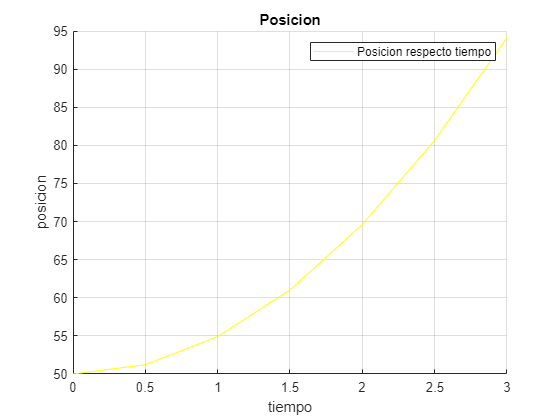


% Grafica la Posicion respecto al tiempo 
clf;
hold on
plot(t,z1,'y')
title("Posicion")
legend("Posicion respecto tiempo")
xlabel("tiempo")
ylabel("posicion")
grid on
hold off

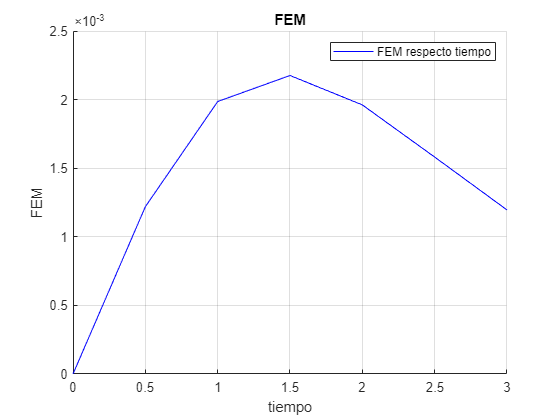


% Grafica fem respecto al tiempo
clf;
hold on
plot(t,FEM,'b')
title("FEM")
legend("FEM respecto tiempo")
xlabel("tiempo")
ylabel("FEM")
grid on
hold off

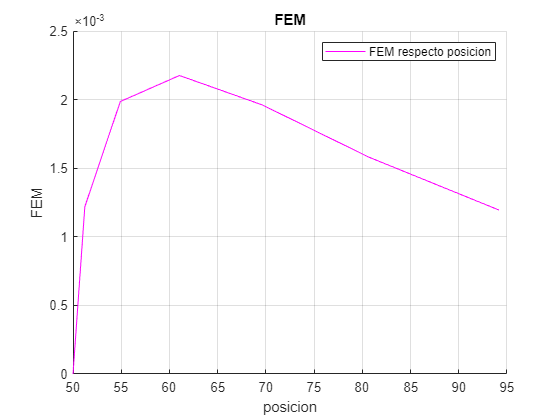


% Grafica fem respecto a la posicion
clf;
hold on
plot(z1,FEM,'m')
title("FEM")
legend("FEM respecto posicion")
xlabel("posicion")
ylabel("FEM")
grid on
hold off

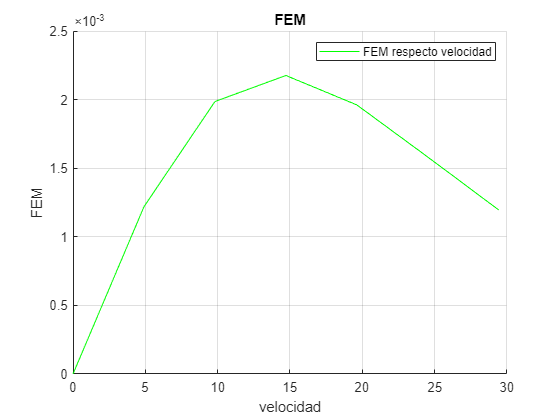


% Grafica la fem respecto a la Velocidad 
clf;
hold on
plot(V,FEM,'g')
title("FEM")
legend("FEM respecto velocidad")
xlabel("velocidad")
ylabel("FEM")
grid on
hold off


% Flujo del campo magnetico
% A = pi*r^2; %Superficie
% vel = % velocidad por segundo
% fi = (M0.*N.*I./z).*A; %Flujo magnetico
% fi = B.*A %Flujo 
% Integrar 
% plot(z,fi,'*b');
% plot(t,fi,'-m-);
% grid on

% (Fg - Fz) / m         (Fg(masa*gravedad) - Fz(%B.*A -> Flujo(fi))) / m

% fem instantanea, B*A (sin velocidad por que es el punto 0; instantanea)
